% count = 1;
% 
% nPoints = 64;
% linspace_steps = 64;
% original_points = linspace(1.3, -1.3, linspace_steps);
% selected_idx = round(linspace(1, linspace_steps, nPoints));
% 
% exclusions = {'f', 'v', 'c', 'F', 'V', 'meshOutput', 'abaqusData', 'E_effectiveStrain', 'E_effectiveStress'};
% % exclusions = {'abaqusData'};
% 
% % Pre-allocate
% template = cell2struct(cell(size(expectedFields)), expectedFields, 1);
% summaryStruct = repmat(template, 1, linspace_steps);
% 
% for i = original_points(selected_idx)
% 
% defaultFolder = 'D:'; % Changed to external hard drive
% savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties_LinearFinal',sprintf('%.5g_Lattice_Density',i));
% matlabPath=fullfile(savePath,'simulation_results.mat');
% 
% load(matlabPath);
% 
% % Define the expected fields (this might come from the first load)
% expectedFields = fieldnames(resultStruct);
% expectedFields = expectedFields(~ismember(expectedFields, exclusions));
% 
% % For each expected field, check if it exists in resultStruct; if not, assign empty
% for j = 1:numel(expectedFields)
%     fieldName = expectedFields{j};
%     if isfield(resultStruct, fieldName)
%         summaryStruct(count).(fieldName) = resultStruct.(fieldName);
%     else
%         summaryStruct(count).(fieldName) = [];  % Or assign a default value
%     end
% end
% 
% count = count + 1
% end

% savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties_LinearFinal','!Summary');
% matlabPath=fullfile(savePath,'simulation_results_summary.mat');
% 
% save(matlabPath,'summaryStruct', '-v7.3')

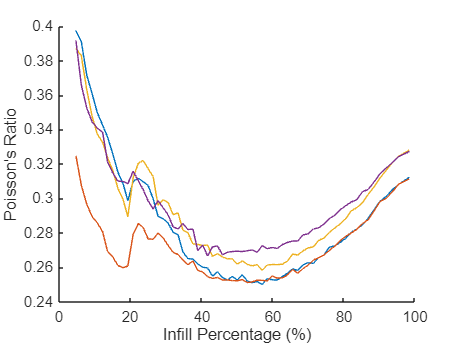

figure;
hold on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xz_mean))
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xy_mean))
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xz_median))
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.poisson_xy_median))

xlabel("Infill Percentage (%)")
ylabel("Poisson's Ratio")

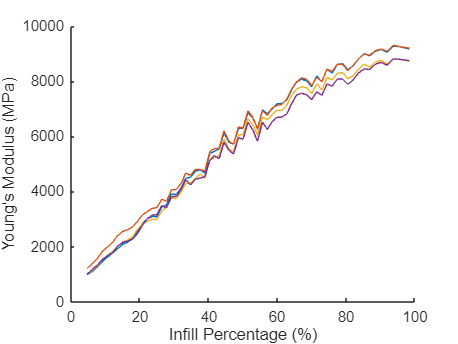

youngs_modulus = vertcat(summaryStruct.youngs_modulus);

figure;
hold on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xz_mean))
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xy_mean))
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xz_median))
plot(vertcat(summaryStruct.infill_percentage), vertcat(youngs_modulus.youngs_modulus_xy_median))

xlabel("Infill Percentage (%)")
ylabel("Young's Modulus (MPa)")

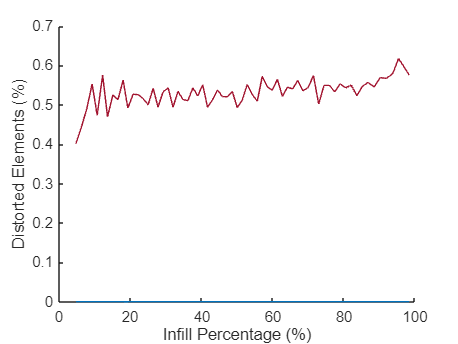

figure;
hold on;
plot(vertcat(summaryStruct.infill_percentage), (vertcat(summaryStruct.distortedElements)/vertcat(summaryStruct.numElements)*100))

xlabel("Infill Percentage (%)")
ylabel("Distorted Elements (%)")

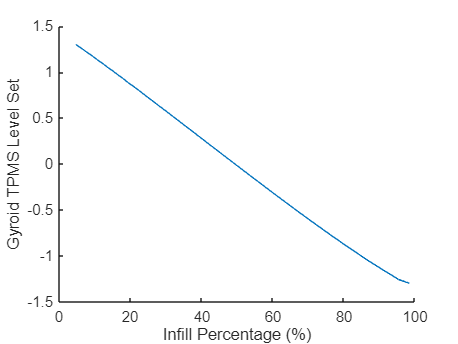

figure;
hold on;
plot(vertcat(summaryStruct.infill_percentage), vertcat(summaryStruct.level_set))

xlabel("Infill Percentage (%)")
ylabel("Gyroid TPMS Level Set")

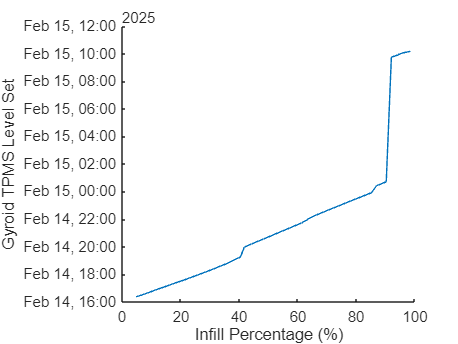

% Extract timestamp strings from the struct array
timestampStrings = {summaryStruct.timestamp};

% Convert to datetime array
timestamps = datetime(timestampStrings, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

figure;
hold on;
plot(vertcat(summaryStruct.infill_percentage), timestamps)

xlabel("Infill Percentage (%)")
ylabel("Gyroid TPMS Level Set")